#### **載入一個預訓練模型，並使用該模型對給定的影像進行辨識。然後，它會顯示影像，標題顯示了預測的類別以及其對應的分數。最後，它列出了前兩高的類別和相應的分數**

**載入模型與影像(Load Model & Image)**

net = trainedNetwork_1;
img = imread("52_AL.jpg");

**影像辨識(Image Classify)**

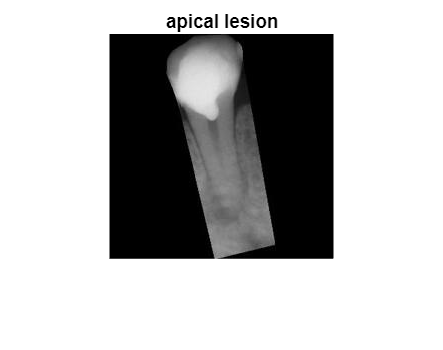

inputSize = net.Layers(1).InputSize(1:2);
classes = net.Layers(end).Classes;

re_img = imresize(img,inputSize);
figure,imshow(re_img)

[YPred,scores] = classify(net,re_img);
title(char(YPred))

**前兩高類別(Top 2 Class)**

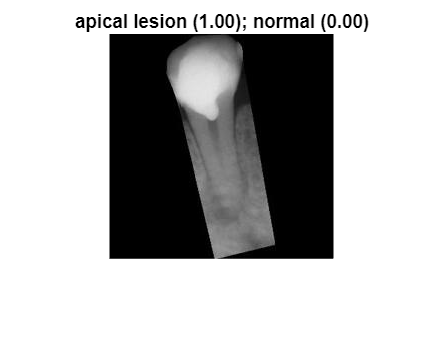

%% List top 2 class scores
[~,topIdx] = maxk(scores, 2);
topScores = scores(topIdx);
topClasses = classes(topIdx);

imshow(re_img)
titleString = compose("%s (%.2f)",topClasses,topScores');
title(sprintf(join(titleString, "; ")));